% Author: Gerardo Parra
clear

%% parameters for running batch script
% parameters for loading data
task      = 'tss';
beapp_tag = '_25hzLP_32hzNF';
file_tag  = [beapp_tag '_2023-04-28_gp'];
data_path = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      'EEG','Participant_Data','03_Processed_Data' );

%% parameters for SP2 data
sp2_path  = fullfile(data_path,'01_Subject_Info_For_Processing','SP2_Processed_2023-04-28');
sp2_field = 'Sensitivity Domain';

% parameters for processing
method    = 'conds_avg';
rois      = {'E30E36E41'};
groups    = {'TD','ASD'};
erps      = {'P50','P100','N140','P300','P4','P100_N140_dist','N140_P300_dist','P4_N140_dist'};  % components to calculate/plot
exclude   = {};

% parameters for plots
cond_to_plot = 4;
save_figs    = false;
norm_data    = false; rm_outliers  = true;
corr_type    = 'Pearson';
cond_names   = {'Index','Middle','Both'};
% colors    = {'#4444c9','#32a852','#db4214'};
% colors     = {'#000','#444','#888','#ccc'};
colors     = {[0 0.4470 0.7410],[0.1961 0.6588 0.3216],[0.8500 0.3250 0.0980]};
colors     = {[0.1961 0.6588 0.3216],[0 0.4470 0.7410],[0.8500 0.3250 0.0980]};
markers    = {'o','+','*'}; markers    = {'+','o','*'};
% colors     = {[0.1961 0.6588 0.3216],[0.8500 0.3250 0.0980]};
x_label    = 'Group';
y_label    = 'Average Amplitude (\muV)';
xlims      = [1 3];

%% load sp2 data
sp2 = readtable(sp2_path,'PreserveVariableNames',true,'ReadRowNames',true);
sp2 = rmmissing(sp2(:,{sp2_field}));

%% load erp batch information
task_path = get_task_path(task);
fig_path  = fullfile(data_path,task_path,'figures','correlations');
task_path_batch = fullfile(data_path,task_path,'erp',['erp' file_tag '.mat']);
load(task_path_batch,'batch');
if norm_data, method = [method '_norm']; end
batch.method = method;
tables = sort_data_into_group_tables(batch,exclude,cond_names,rois);

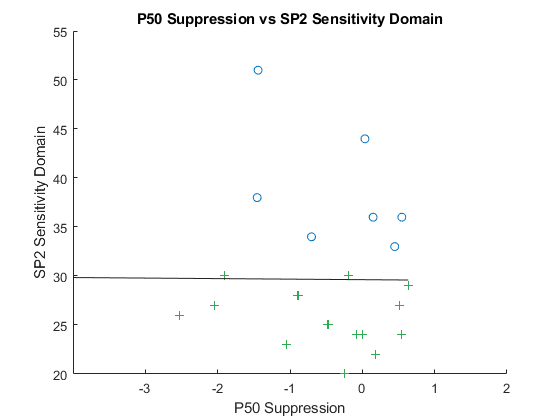

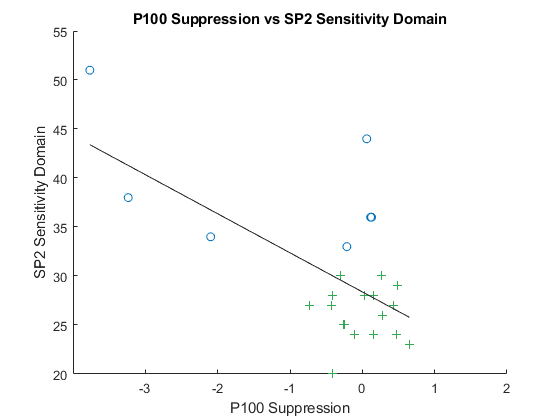

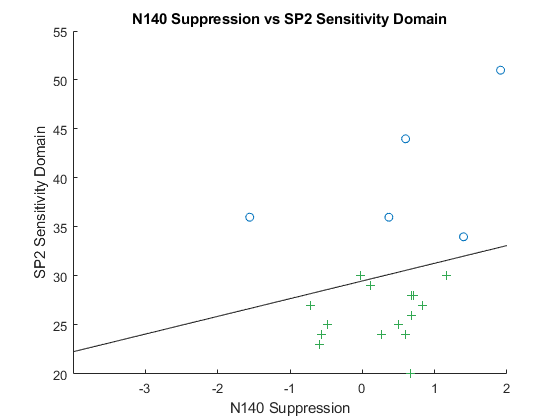

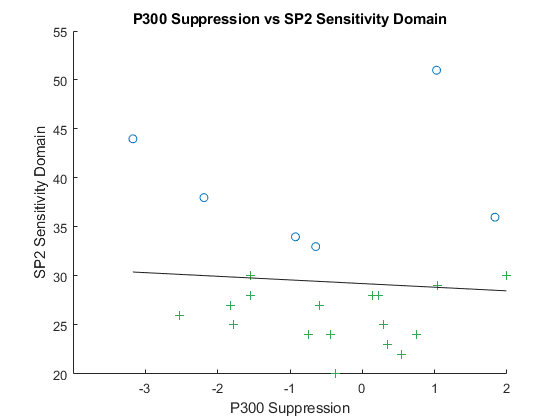

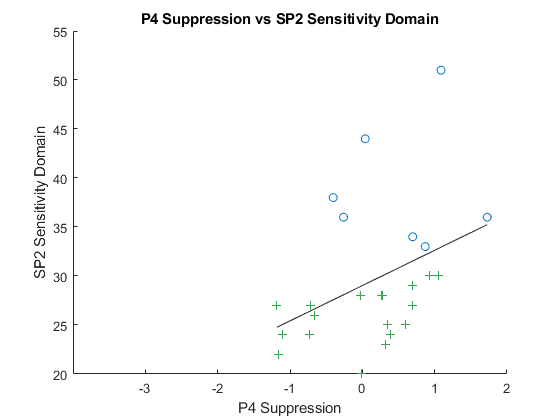

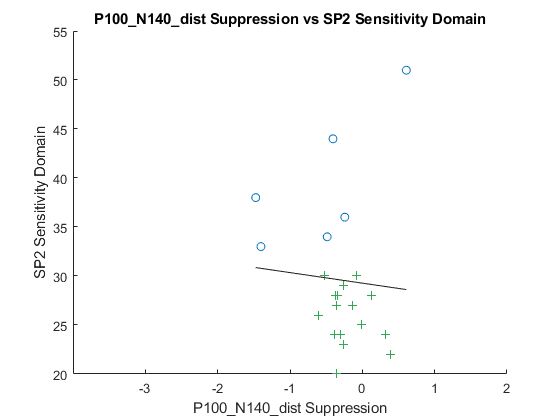

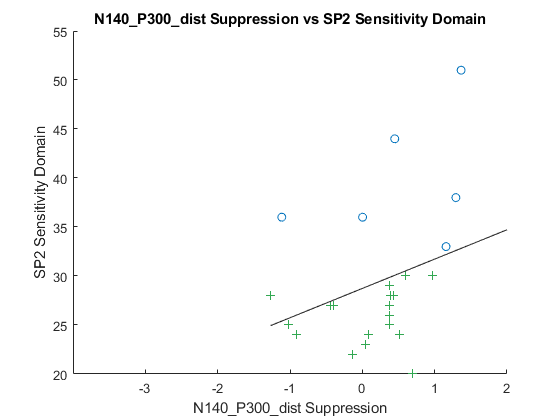

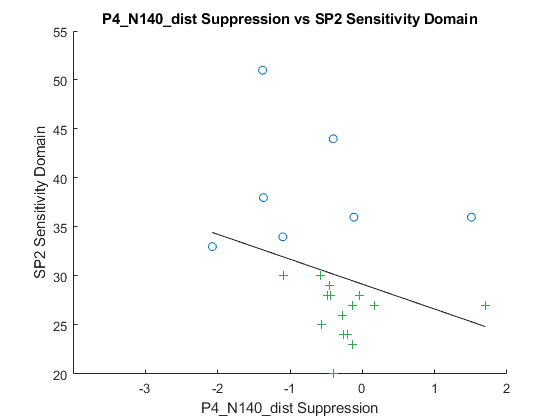

%% iterate through tables and plot 
n_groups = length(groups);
n_rois   = length(rois);
n_erps   = length(erps);
for i_r = 1:n_rois
    roi = rois{i_r};
    for i_e = 1:n_erps
        erp = erps{i_e};
        if ~isfield(tables.TD.(roi),erp), continue; end
        
        f = figure; hold on
        group_erp = cell(1,n_groups); group_sp2 = cell(1,n_groups);
        for i_g = 1:n_groups
            % get ids of participants with SP2 AND ERP data
            group = groups{i_g};
            group_table = tables.(group).(roi).(erp);
            group_ids   = intersect(group_table.Properties.RowNames,sp2.Properties.RowNames);

            % add suppression index for tss
            if strcmp(task,'tss')
                % get values by condition
                grp_im = group_table{:,1} + group_table{:,2};
                grp_b = group_table{:,3};
                
                % deal with negative peaks
                if contains(erp,'N') %&& ~contains(erp,'dist')
                    grp_im = grp_im * -1; grp_b = grp_b * -1; 
                end
                % get percent change
                sf = (grp_im - grp_b) ./ grp_im;
                sf(grp_im<0) = sf(grp_im<0) * -1;
                group_table.Suppression = sf;
            end
            
            % get data of all valid participants
            group_erp{i_g} = group_table{group_ids,:}(:,cond_to_plot);
            group_sp2{i_g} = sp2{group_ids,:};
            group_label{i_g} = [groups{i_g} ', n=' int2str(length(group_ids))];

            % remove outliers
            if rm_outliers
                outliers = logical((abs(zscore(group_erp{i_g}))>2) + (abs(zscore(group_sp2{i_g}))>2));
                group_erp{i_g}(outliers) = []; group_sp2{i_g}(outliers) = [];
            end
            
            % create scatterplot
            scatter(group_erp{i_g},group_sp2{i_g},'MarkerEdgeColor',colors{i_g},'Marker',markers{i_g})

            % add labels
            cond_label = group_table.Properties.VariableNames{cond_to_plot};
            plot_title = [erp ' ' cond_label ' vs SP2 ' sp2_field]; % upper(task) ' ' roi ' ' 
            title(plaintext(plot_title))
            xlabel(plaintext([erp ' ' cond_label])); ylabel(plaintext(['SP2 ' sp2_field]))
            xlim([-4 2]); xticks(-3:3)
        end
        % correlate measures
        all_erp = cell2mat(group_erp'); all_sp2 = cell2mat(group_sp2');
        [r,pf] = corr(all_erp,all_sp2,'Type',corr_type);
%         str=sprintf('r=%1.2f,p=%1.4f',r,pf);
%         T = text(min(get(gca, 'xlim')), max(get(gca, 'ylim')), str); 
%         set(T,'fontsize',10,'verticalalignment','top','horizontalalignment','left');
        % add line of best fit
        pf = polyfit(all_erp,all_sp2,1);
        y_fit = polyval(pf,all_erp);
        plot(all_erp,y_fit,'Color','#222','DisplayName','Line of best fit')
%         legend(group_label,'Location','best')
        % save figure
        if save_figs
            % get and create file path, if necessary
            if ~exist(fig_path,'dir')
                mkdir(fig_path)
            end
        
            % get figure name and save
            fig_fname = [strrep(plot_title,' ','_') '_' method beapp_tag];
            exportgraphics(f,fullfile(fig_path,[fig_fname '.jpg']),'Resolution',300)
        end
        pause(0.2)
    end
end